## S波超导

参考自[一些简单的超导体模型 - 知乎](https://zhuanlan.zhihu.com/p/600284125)

[s波d波超导体的态密度与谱函数 - 知乎](https://zhuanlan.zhihu.com/p/603315345)

哈密顿量为


$$H=-t\sum_{\langle ij\rangle\sigma}c_{i\sigma}^\dagger c_{i\sigma}+\sum_i\Delta c_{i\uparrow}^\dagger c_{i\downarrow}^\dagger+H.c.-\sum_{i\sigma}\mu_i c_{i\sigma}^\dagger c_{i\sigma}$$


### 参数设置

% N_Spin = 2;
clear;
mu = -0.5;
t = 1;
Delta = 0.3;
a = 1;
N_col = 20;
N_row = N_col;
N_site = N_col * N_row;
N_spin = 2;
N_tot = N_site * N_spin;

### Nambu基得到BdG哈密顿量


$$\psi=\left(\vec{c}_\uparrow,\vec{c}^\dagger_\downarrow\right)$$


%% Work in Nambu basis \psi = (c_up, cdag_down)T
Hopping = get_Nearest_Square_Hopping_Sparse(N_col, N_row, t, t);
h_chemical_potential = -mu * eye(N_site);
h_offdiagonal = Delta * eye(N_site);
H = [h_chemical_potential + full(Hopping), h_offdiagonal;
    h_offdiagonal, -h_chemical_potential - full(Hopping)];

对角化得到能谱并画图

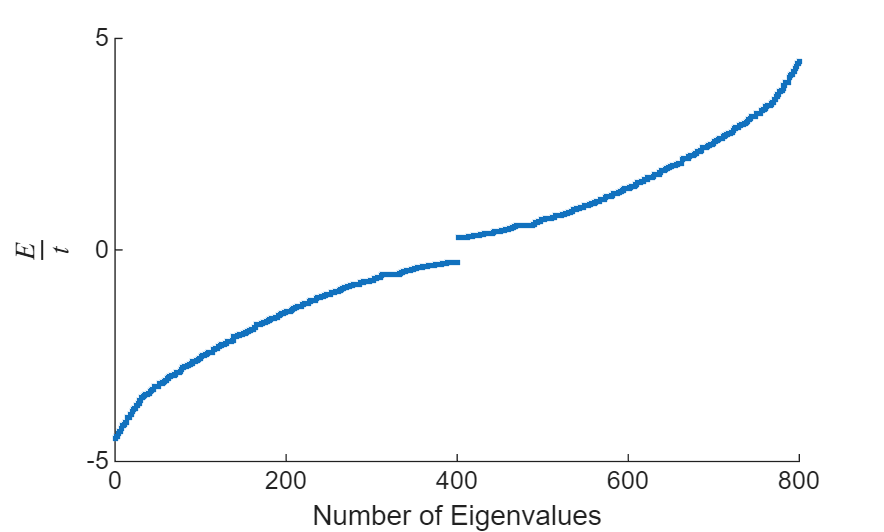

[Wave, Eigen] = eig(H);
[Eigen, perm] = sort(diag(Eigen));
Wave = Wave(:,perm);

figure
scatter(1:length(Eigen),Eigen,'.')
xlabel("Number of Eigenvalues");
ylabel("$\frac{E}{t}$","Interpreter","latex")

波函数

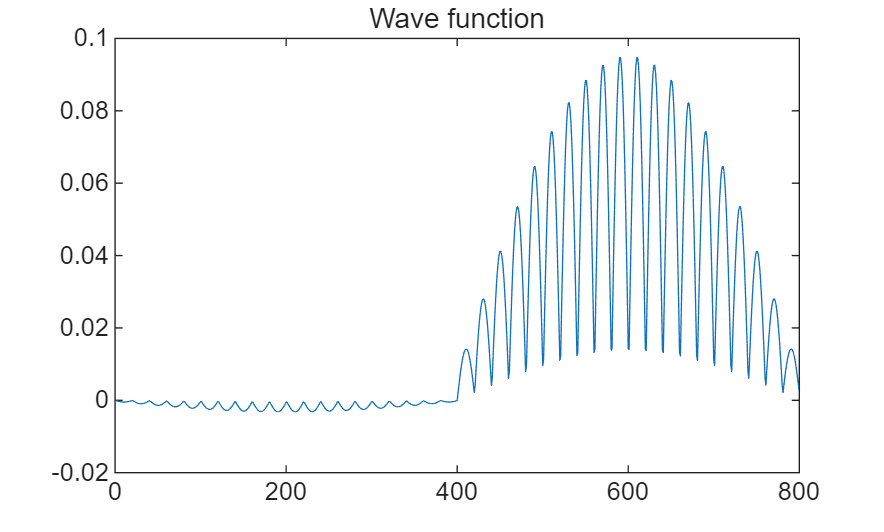

figure
Count = 1;
plot(Wave(:,Count))
title("Wave function")

态密度

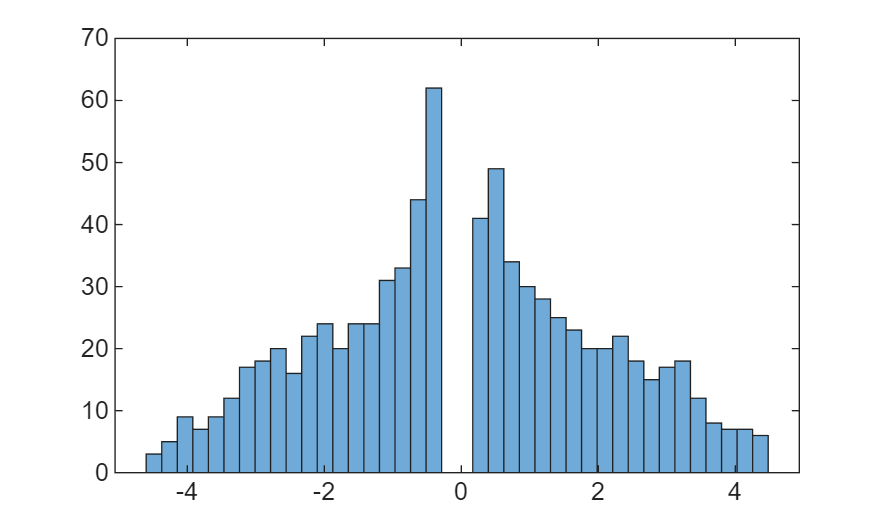

figure
h = histogram(Eigen, N_site/10);

若取x方向为周期性边界条件，哈密顿量变为


$$H=\sum_{k_x,n \sigma}(-2t\cos k_x -\mu)c_{k_x\sigma,n}^\dagger c_{k_x\sigma,n}+\left(\sum_{k_x,n\sigma} -tc_{k_x\sigma,n}^\dagger c_{k_x\sigma,n+1}+\sum_{k_x,n}c_{k_x,\uparrow n}^\dagger c_{-k_x,\downarrow n}^\dagger + H.c.\right)$$


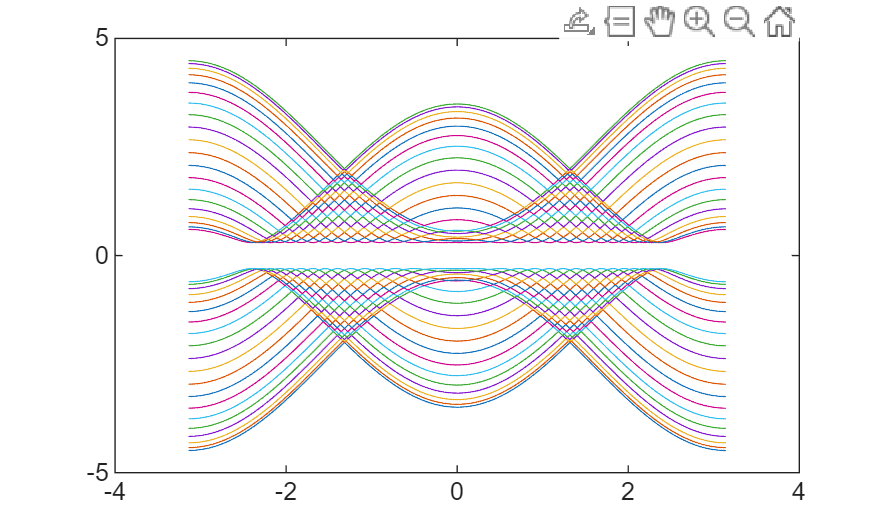

kx_step = 101;
kx = [-pi,pi];
kx_list = linspace(kx(1), kx(2),kx_step);

energy_band = zeros(N_spin * N_row, kx_step);
for ii = 1: length(kx_list)
    H_diag = (-2 * t * cos(kx_list(ii)) - mu) * eye(N_row)...
            - t * diag(ones(1, N_row-1),1) - t * diag(ones(1, N_row-1),-1);
    H = [H_diag, Delta * eye(N_row);
         Delta * eye(N_row), -H_diag];
    energy_band(:, ii) = eig(H);
end

plot(kx_list, energy_band)

若取两个方向都为周期性边界条件，哈密顿量变为


$$H=\sum_{k\sigma}\left[-2t(\cos k_x +\cos k_y)-\mu\right]c_{k\sigma}^\dagger c_{k\sigma}+\sum_{k}\left(\Delta c_{k\uparrow}^\dagger c_{-k\downarrow}^\dagger+H.c.\right)$$


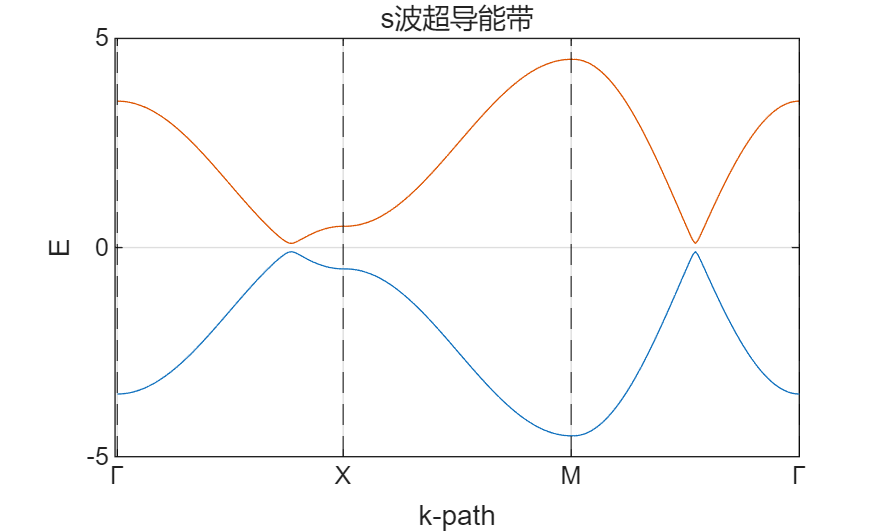

k_step = 101;
H = @(kx, ky) [(-2 * t * (cos(kx)+cos(ky)) - mu), Delta;
              Delta, -(-2 * t * (cos(kx)+cos(ky)) - mu)];
energy_band = zeros(3*k_step, N_spin);

% Define high-symmetry points in the Brillouin zone
Gamma = [0, 0]; % Gamma point (0,0)
X = [pi/a, 0];  % X point (pi/a, 0)
M = [pi/a, pi/a]; % M point (pi/a, pi/a)

% Define k-path: Gamma -> X -> M -> Gamma
k_path = [];
% Gamma to X
k1 = linspace(0, 1, k_step);
k_path = [k_path; k1'*X];
% X to M
k2 = linspace(0, 1, k_step);
k_path = [k_path; X + k2'*(M-X)];
% M to Gamma
k3 = linspace(0, 1, k_step);
k_path = [k_path; M + k3'*(Gamma-M)];

for ii = 1:size(k_path,1)
    energy_band(ii, :) = eig(H(k_path(ii, 1), k_path(ii, 2)));
end

% Plot the band structure
figure;
plot(1:size(k_path,1), energy_band);
hold on;

% Mark high-symmetry points
xticks = [1, k_step, 2*k_step, 3*k_step];
xticklabels = {'\Gamma', 'X', 'M', '\Gamma'};
set(gca, 'XTick', xticks, 'XTickLabel', xticklabels);
xlabel('k-path');
ylabel('E');
grid on;
title('s波超导能带')
% Add vertical lines at high-symmetry points
for i = xticks
    xline(i, 'k--');
end
axis([0, 3*k_step, -5, 5])

态密度

kx =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317
   -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -

ky =    -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416
   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -3.0781   -